# Example myBspline class code

Fit the function y = x.sin( x ) on the interval [0, 10]. Gaussian noise is added to the data.

## 1. Create training data

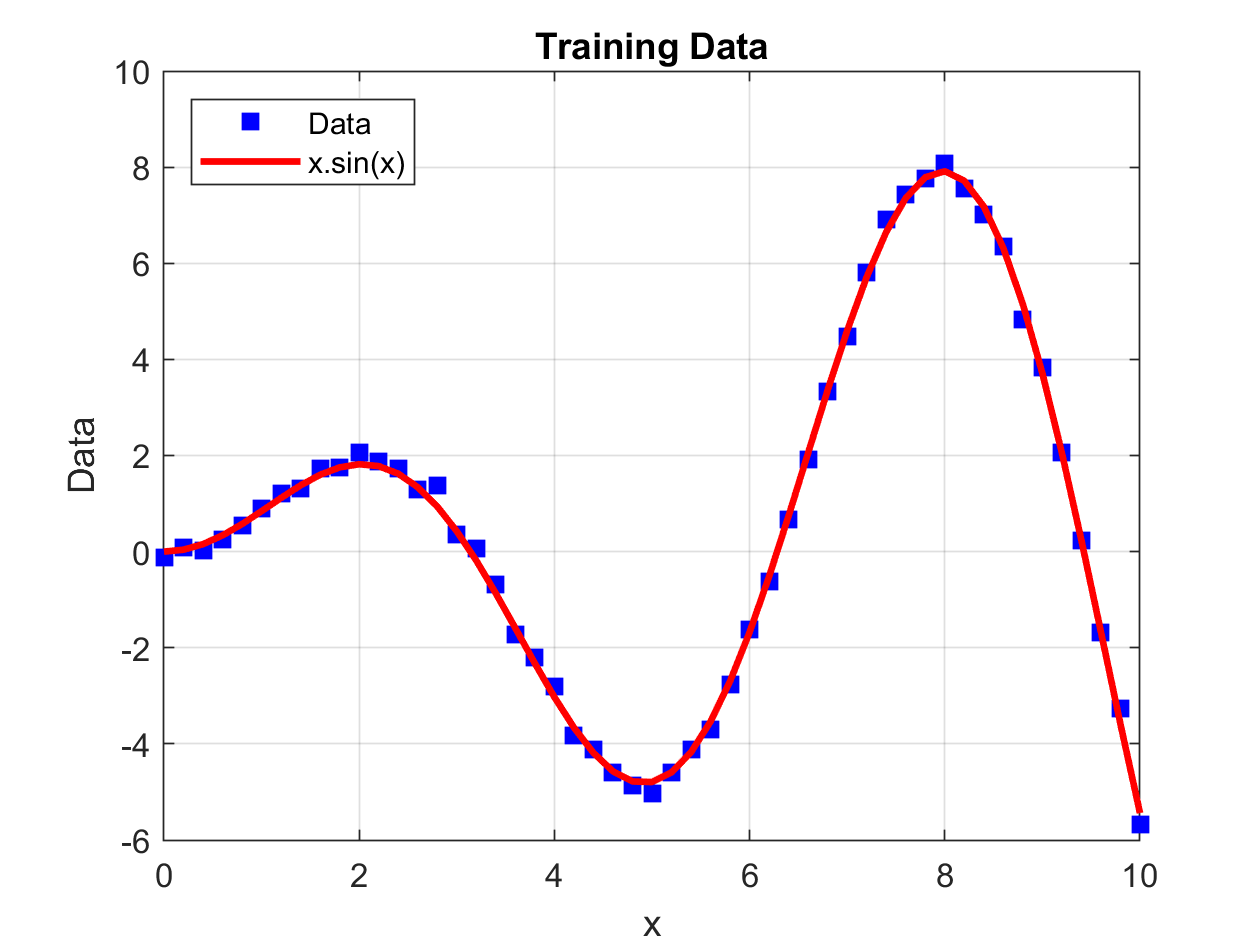

%% Create training data and plot
X = linspace( 0, 10, 51 ).';
Fcn = X.*sin( X );
Y = Fcn + 0.15*randn( 51, 1 );
Ax = axes();
H = plot( X, Y, 'bs', X, Fcn, 'r-');
H( 1 ).MarkerFaceColor = "blue";
H( 2 ).LineWidth = 2;
grid on;
ylabel( "Data");
xlabel( "x" );
title( Ax, "Training Data");
legend( "Data" , "x.sin(x)", 'Location', "northwest")

## 2. Create myBspline objects & Perform Fitting

D = 3;          % Degree of interpolating polynomial
KMax = 20;       % Maximum number of knots
A = 0;                             % Low input data limit for coding
B = 10;                            % High input data limit for coding
P = zeros( numel(X), 9);           % Predictions
S( KMax ) = bSplineTools( D, 1, A, B);
for NK = KMax:-1:1
    KS = sort( rand( NK, 1 ) );    % Coded knots
    KS = S( NK ).decode( KS );     % Assign knots in natural units
    S( NK ) = bSplineTools( D, KS, A, B);    
    S(NK) = S(NK).fit( X, Y );
    P(:,NK) = S(NK).eval( X );
end

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      21    1.094051e+02    0.000e+00    2.328e+03
    1      48    7.489903e+01    0.000e+00    8.475e+02    1.867e-01
    2      72    7.314431e+01    0.000e+00    1.712e+03    3.699e-02
    3      93    6.199428e+01    0.000e+00    1.484e+03    7.482e-01
    4     114    5.783230e+01    0.000e+00    1.609e+03    1.479e-02
    5     144    5.464212e+01    0.000e+00    7.318e+02    1.840e-02
    6     166    5.157126e+01    0.000e+00    8.203e+02    1.850e-02
    7     192    4.242687e+01    0.000e+00    2.446e+02    1.792e-02
    8     215    3.991181e+01    0.000e+00    3.091e+02    1.780e-02
    9     240    3.538411e+01    0.000e+00    4.038e+02    3.660e-02
   10     264    3.409815e+01    0.000e+00    1.799e+02    1.687e-02
   11     290    2.948552e+01    0.000e+00    1.026e+02    1.867e-02
   12     314    2.920682e+01    0.000e+00    9

## 3. Compare Fits

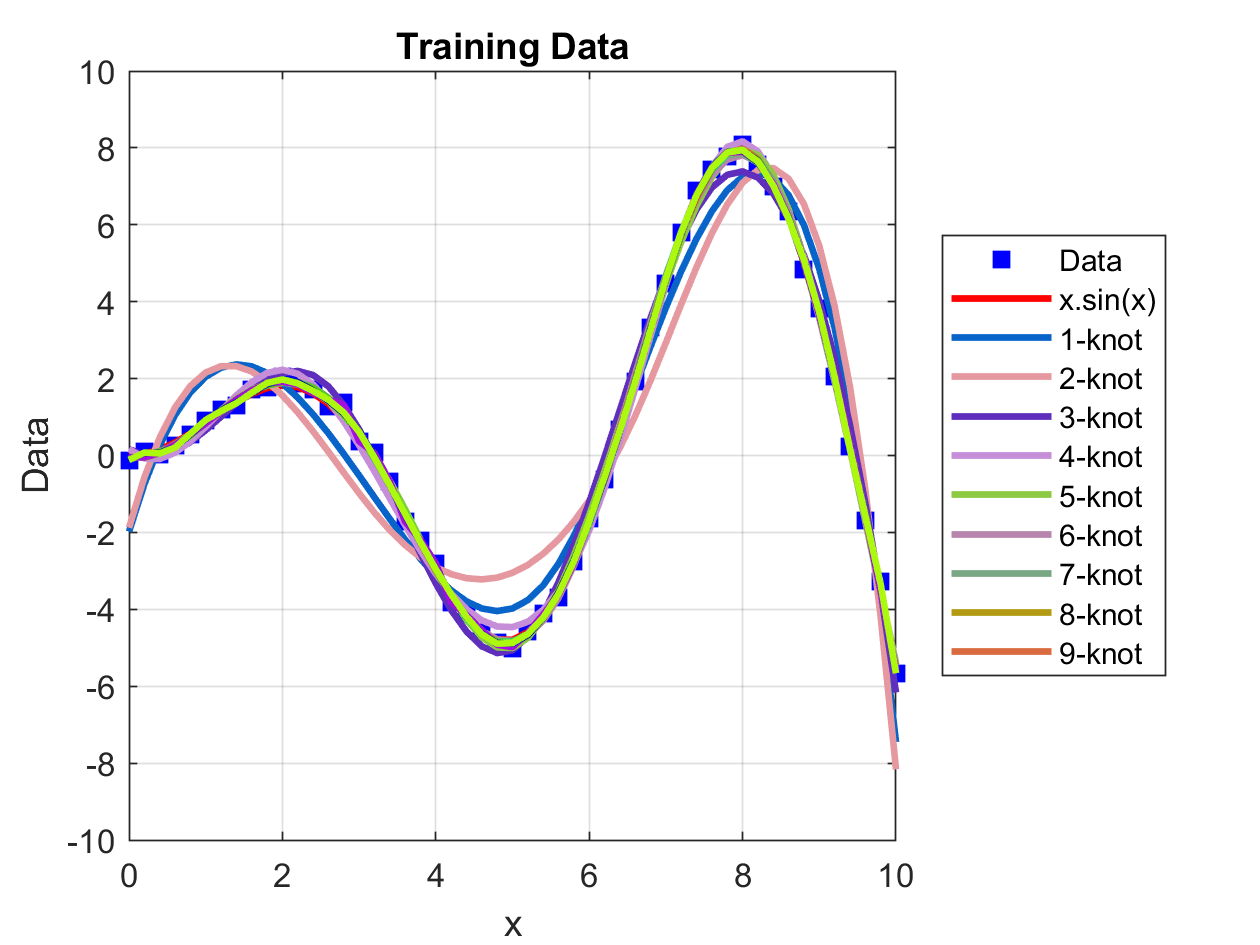

Ax.NextPlot = "add";
for NK = 1:KMax
    H( 2 + NK ) = plot( X, P( :, NK ), '-' );
    H( 2 + NK ).LineWidth = 2;
    H( 2 + NK ).Color = rand( 1, 3 );
end
legend( "Data" , "x.sin(x)", "1-knot", "2-knot", "3-knot", "4-knot", "5-knot",...
    "6-knot", "7-knot", "8-knot", "9-knot", 'Location', "eastoutside", "Orientation",...
    "vertical");

## 4. Model Selection

Use AIC measure to select model

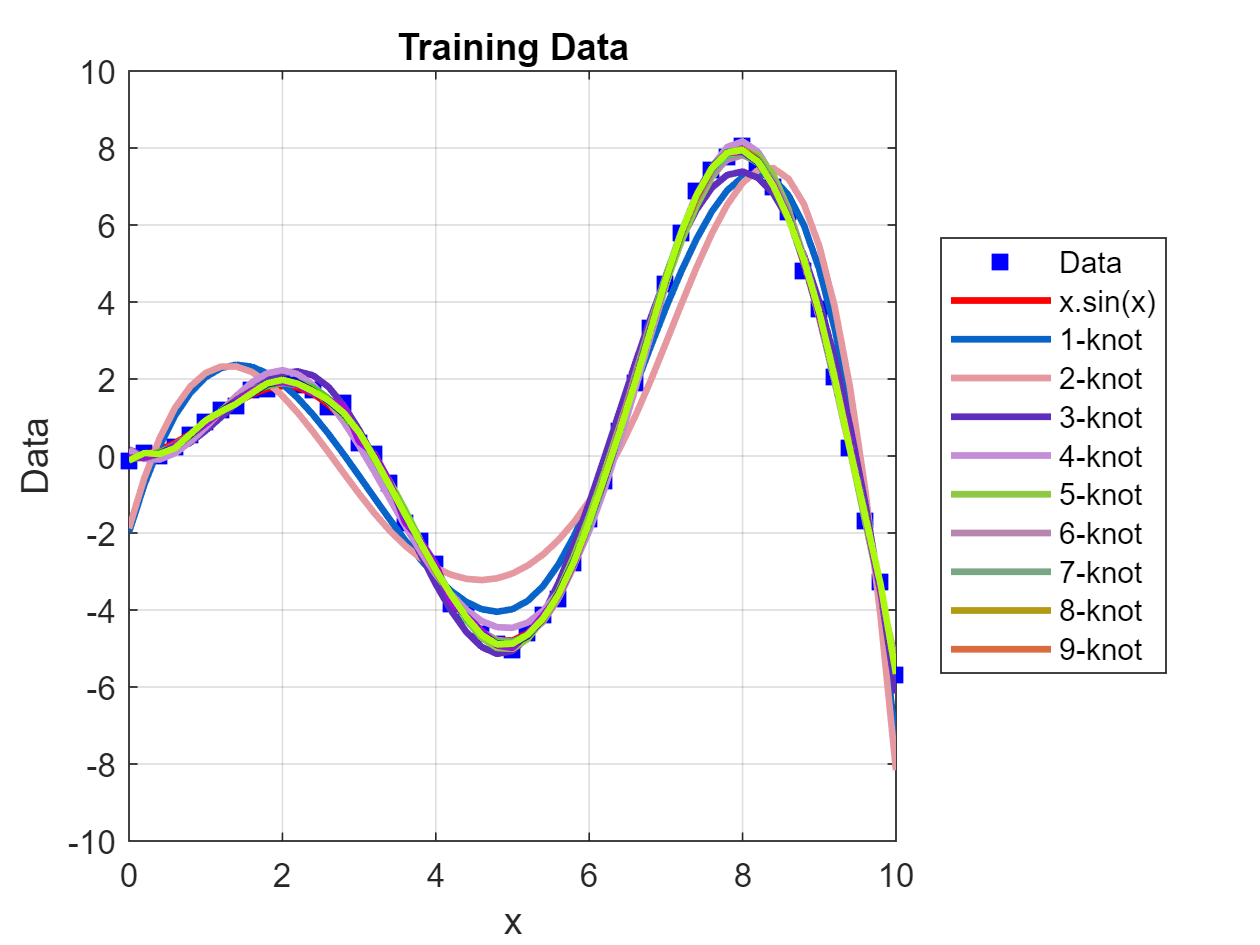

AIC = [ S.AIC ];
figure;
Ax( 2 ) = subplot(2,1,1);
H( end + 1 ) = plot( 1:KMax, AIC, 'bs-' );
H( end ).LineWidth = 2;
H( end ).MarkerFaceColor = 'blue';
H( end ).MarkerSize = 8;
grid on
% select model
[ ~, M ] = min( AIC );
Ax( 2 ).NextPlot = "add";
H( end + 1 ) = plot( M, AIC( M ), 'gp' );
H( end ).MarkerFaceColor = "green";
H( end ).MarkerSize = 10;
xlabel( "Number of Knots");
ylabel( "AIC_c " );
legend( "AIC", "Best", "Location", "northeast");
title("Best model selection");
Ax( 3 ) = subplot(2,1,2);
K = plot( X, Y, 'bs', X, Fcn, 'r-', X, P( :, M ), 'g-', 'MarkerFaceColor', 'blue',...
          'LineWidth', 2 );
Ax( 3 ).NextPlot = "Add";
K( end + 1 ) = plot( S( M ).n, min( Ax( 3 ).YLim ) * ones( S( M ).k, 1), 'b^', ...
    'MarkerFaceColor', 'blue' );
grid on
xlabel( "x" );
title( Ax, "Training Data");

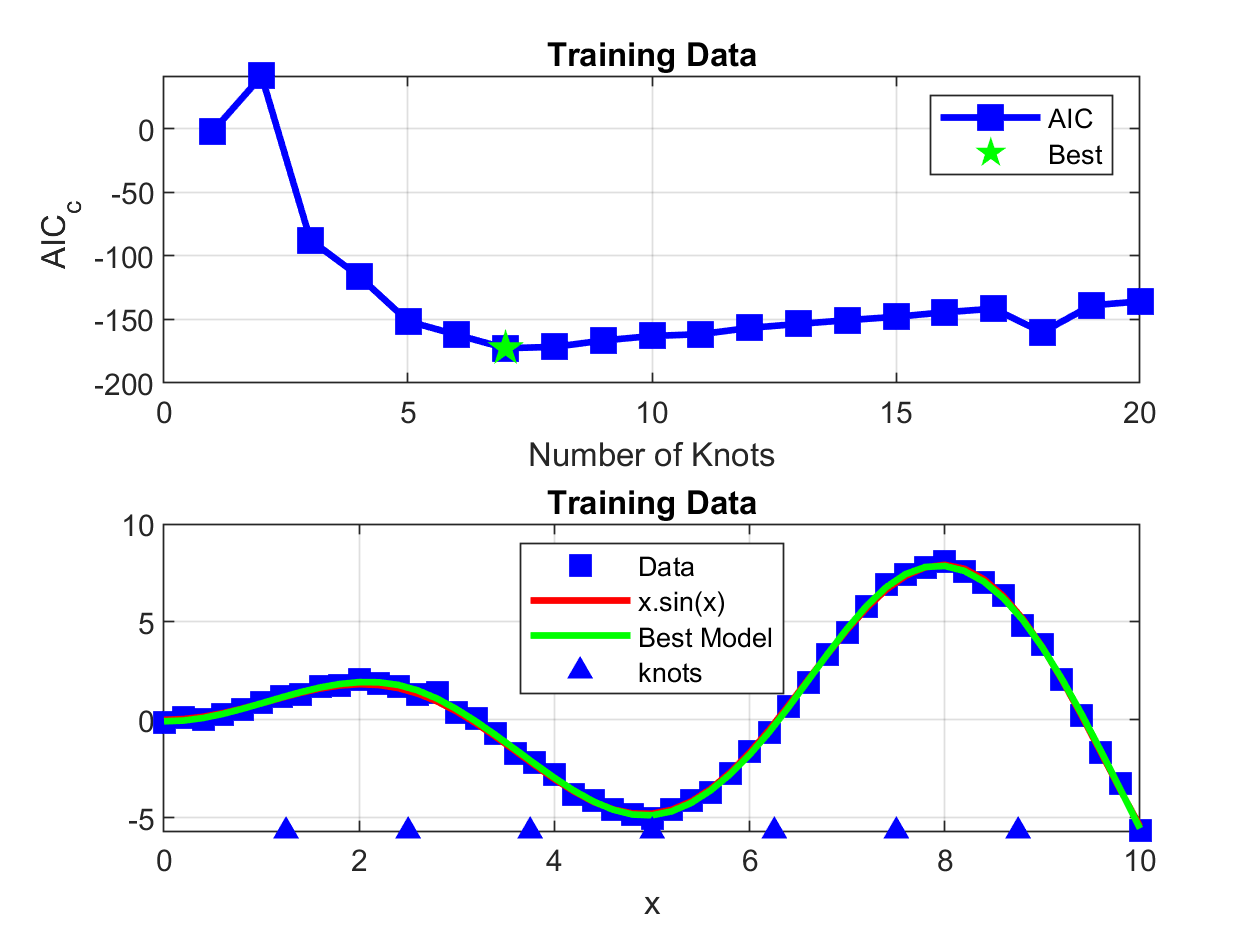

legend( "Data" , "x.sin(x)", "Best Model", "knots", 'Location', "north")